*Copyright (c) 2024 by Central South University.*

`coding: utf-8`

## Test the time the function runs.

*Programme written by Y. Yang*

*For more information, contact by email: <yangyaokun@csu.edu.cn>.*

Please read the README.md before use.

clearvars

model = [-50,50,-50,50,-150,-50,2000];
area = ObservationPlane(model);

## test the cost time

n = 11*ones(1,3);

tic
CuboidGravity_GaussianQuad(model,area,'method','l','n',n);
toc

历时 3.632060 秒。


## plot the cost time

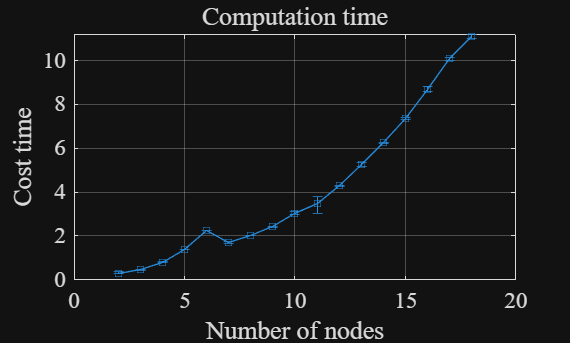

load Data\CostTimeofGaussianQuad.mat

n = t(:,1);
t = t(:,2:5);

cv = mean(t,2);
pos = max(t,[],2) - cv;
neg = min(t,[],2) - cv;

figure
errorbar(n,cv,neg,pos,'-s','MarkerSize',5)
grid on
xlabel('Number of nodes')
ylabel('Cost time')
title('Computation time')
ax = gca;
ax.FontName = 'Times New Roman';
ax.FontSize = 14;